# **Optimizing inverter dispatch for overvoltage prevention in radial feeder system using linear approximations of power flow constraints**

The rising craze for PV installation especially in low voltage distribution system brings about the problem of local voltage rise. The voltage rise is related to the amount of active(P) and reactive power(R) injected at a particular local bus by this relation,


$$\Delta \;V=\frac{\mathrm{PR}+\mathrm{QX}}{V}\;$$


The R and X are the resistance and reactance of feeder line connecting local bus to the substation and V is the nominal voltage at the substation. The ANSI C8.1 standard doesnot allow the voltage above 1.058 p.u. Due to the resistive characteristics of the distrbution feeder active power injection has dominant effect on the voltage rise than the reactive power. In this study, we are going to find optimal way of dispatching inverter power to have minimum curtailment avoiding the issue of overvoltage and unfairness. First we will analyze the the situation assuming every houses operating at unity power factor. Secondly we will deal with situation what happens if we allow power factor upto 0.95.

# Description of benchmark system

A 12 house benchmark system from [1] is considered for the case study. It is a typical radial distrbution feeder of a rural area. One substation transformer of 75kVA capacity supplies electricity to 12 houses each installed with 8.4 kW roof top solar. The PV power is injected into the distribution system via "smart inverter". 

[1] R. Tonkoski, L. A. C. Lopes and T. H. M. El-Fouly, "Coordinated Active Power Curtailment of Grid Connected PV Inverters for Overvoltage Prevention," in *IEEE Transactions on Sustainable Energy*, vol. 2, no. 2, pp. 139-147, April 2011.

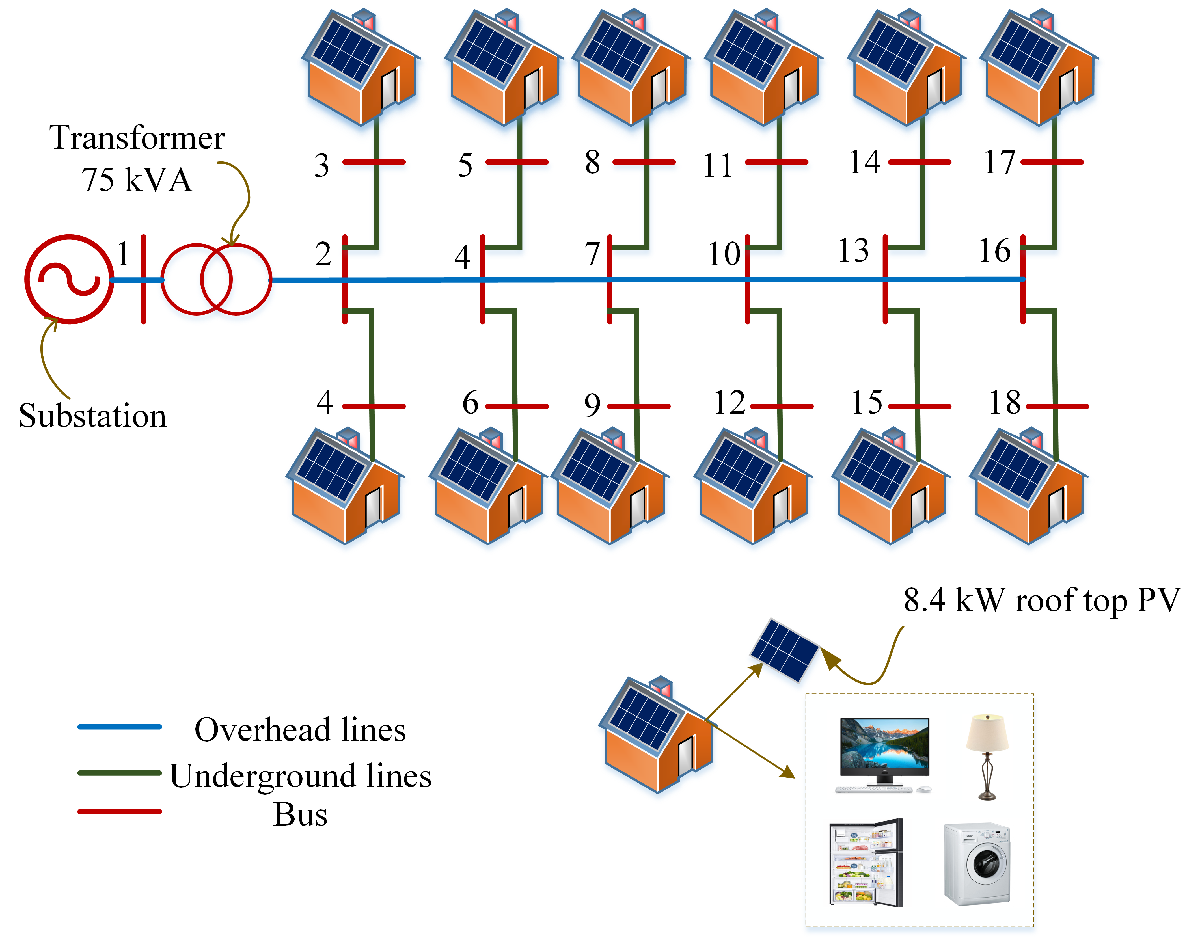

# Problem formulation

**Objective: **$\underset{\left\lbrace P_{i,t} ,Q_{i,t} ,V_{i,t} \right\rbrace }{\mathrm{Minimize}} \;\sum_{i=1}^{n_{h\;} } \sum_{t=1}^T \left(P_{i,t\;}^{\mathrm{mppt}} -P_{i,t} \right)$; Minimize total curtailment

**Constraints:**

$V_t =R\left(P_t -L_t^P \right)+B\left(Q_t -L_t^Q \right)+a,\forall \;t\epsilon \;T$ { Linearized power flow equation for voltage magnitude} [2]

$V^{\mathrm{min}} \le V_{i,t} \le V^{\mathrm{max}}$, $i\epsilon \;n_{b\;} ,t\epsilon \;T$ { Voltage of each bus should be within minimum and maximum limits for all time }

$0\le P_{i,t} \le \left(P_{i,t}^{\mathrm{mppt}} \right),i\epsilon \;n_{h\;} ,t\epsilon \;T$ { Active power dispatch of the inveter should be limited within MPPT power and cannot absorb active power }

$0\le P_{i,t} \le 0,i\epsilon \;\left\lbrace n_{h\;} \not= n_b \right\rbrace ,t\epsilon \;T$ {Buses with no PV inverters must have 0 generation}

**Variables discription:**

$n_h$ = Set of PV houses or inverters

$n_b$ = Set of buses in the distribution system

$P_{i,t} \;$= Active power of $i^{\mathrm{th}\;}$inverter at $t^{\mathrm{th}\;}$time

$Q_{i,t} \;$= Reactive power of $i^{\mathrm{th}\;}$inverter at $t^{\mathrm{th}\;}$time

$V_{i,t} \;$= Voltage of $i^{\mathrm{th}\;}$inverter at $t^{\mathrm{th}\;}$time

*R, B, a *are linearized power flow constraints for given radial distribution network

$V_{t\;}$is the vector of bus voltage magnitudes for $t^{\mathrm{th}\;} \;$time

$P_{t\;}$is the vector of bus powers for $t^{\mathrm{th}\;} \;$time

$Q_{t\;} \;$is the vector of bus reactive powers for $t^{\mathrm{th}\;} \;$time

$L_t^P$ is the vector of loads at each buses for $t^{\mathrm{th}\;} \;$time

# **Getting R, B & a for 12 house benchmark system**

[2] S. V. Dhople, S. S. Guggilam and Y. C. Chen, "Linear approximations to AC power flow in rectangular coordinates," *2015 53rd Annual Allerton Conference on Communication, Control, and Computing (Allerton)*, Monticello, IL, 2015, pp. 211-217

$\left|V\right|=R\times p+B\times q+a$, $p_{\;} ,q$ are the vector of active and reactive power injected at buses


$$R=Z_{R\;} \mathrm{diag}\left(\mathrm{cos}\left(\overset{-}{\theta_n } \right)\right)\left({\mathrm{diag}\left(\overset{-}{V} \right)}^{-1} \right)-Z_{I\;} \mathrm{diag}\left(\mathrm{sin}\left(\overset{-}{\theta_n } \right)\right)\left({\mathrm{diag}\left(\overset{-}{V} \right)}^{-1} \right)$$



$$B=Z_{I\;} \textrm{diag}\left(\cos \left(\overset{-}{\theta_n } \right)\right)\left({\textrm{diag}\left(\overset{-}{V} \right)}^{-1} \right)+Z_{R\;} \textrm{diag}\left(\sin \left(\overset{-}{\theta_n } \right)\right)\left({\textrm{diag}\left(\overset{-}{V} \right)}^{-1} \right)$$



$$Z_R =\Re \left\lbrace Y^{-1\;} \right\rbrace \;\&\;Z_I =\Im \;\left\lbrace Y^{-1} \right\rbrace$$


No load voltage approximation:

As a starting point no load voltage at each bus is taken as starting point. For radial distribution network this will be 1 per unit for all buses. (In our case its 1.02 because transformer had a tap setting at 1.02 pu.

$\overset{-}{V} ={1\ldotp 02}_N$, $\cos \left(\overset{-}{\theta_n } \right)=1_N ,$ $\mathrm{sin}\left(\overset{-}{\theta_n } \right)=0_N$

load R;
load B;
load a;
R_l = R;
B_l = B;
a_l = a;

# **Simulation setup**

The minute resolution irradiance data and load data for one day (June 22, 2014) is considered for simulation. Same irradiance is used for each houses at a given time.

## Visualize load data for each houses

nminutes = 1440;
load loaddata;
Time = 1:nminutes;
h = 9;
figure('color',[1,1,1]);
stairs(Time,loaddatajune22(:,h)/1000,'LineWidth',2);
xlim([1,1440]);
grid on; box on;
title('Load profile')
ylabel('Load (kW)')
xlabel('Time (minutes)')

## Visualize MPPT power output 

figure('color',[1,1,1]);
plot(Time,loaddatajune22(:,1)/1000,':r','LineWidth',2);
xlim([1,1440]);
grid on; box on;
title('Mppt power profile')
ylabel('Power (kW)')
xlabel('Time (minutes)')

## **Setting up data for optimization**

nbus = 18; % Number of buses except reference bus
Mppt = loaddatajune22(:,1)/75000; % grab MPPT data
node = [3,4,6,7,9,10,12,13,15,16,18,19]-1; % Bus number at which PV houses are present
Load = zeros(nminutes,nbus);
Load(:,node) = loaddatajune22(:,2:end)/75000; % Loads are assigned to nodes with houses

VMAX = 1.058; % maximum voltage limit
VMIN = 0.95; % minimum voltage limit

row_voltagemax = VMAX*ones(1,nbus);
row_voltagemin = VMIN*ones(1,nbus);
Vminmatrix = repmat(row_voltagemin,nminutes,1); 
Vmaxmatrix = repmat(row_voltagemax,nminutes,1);


Pmaxmatrix = zeros(nminutes,nbus);
hcol_Pmaxmatrix = repmat(loaddatajune22(:,1)/75000,1,12); % setting the maximum active power injection limit to MPPT power for buses with PV house
Pmaxmatrix(:,node) = hcol_Pmaxmatrix;
Pminmatrix = zeros(nminutes,nbus); % setting minimum active power limit to zero
Qmaxmatrix = zeros(nminutes,nbus); % setting maximum reactive power injection to zero
Qminmatrix = zeros(nminutes,nbus); % setting minimum reactive power injection to zero

# **Case I: Solving optimization considering unity power factor (Not considering fairness)**

## **Define optimization problem and decision variables**

House12opt = optimproblem;
% active power setpoint
act_pow = optimvar('act_pow',nminutes,nbus,'LowerBound',Pminmatrix,'UpperBound',Pmaxmatrix);
% reactive power setpoint
react_pow = optimvar('react_pow',nminutes,nbus,'LowerBound',Qminmatrix,'UpperBound',Qmaxmatrix);
% voltage set point
voltage = optimvar('voltage',nminutes,nbus,'LowerBound',Vminmatrix,'UpperBound',Vmaxmatrix);

## **Setup objective function**

curtail = repmat(Mppt,1,12) - act_pow(:,node);
House12opt.Objective = sum(sum(curtail));

## **Setting up constraints**

House12opt.Constraints.voltagecons = optimconstr(nminutes,nbus);
for i = 1:nminutes

  House12opt.Constraints.voltagecons(i,:) = ...
      voltage(i,:) == (R_l*(act_pow(i,:)-Load(i,:))'+B_l*react_pow(i,:)'+a_l)'; 
end

**Solve optimization**

options = optimoptions('linprog');
% call the optimization solver to find the best solution
[sol,TotalCost,exitflag,output] = solve(House12opt,'Options',options);

## **Results analysis**

Voltage profile for each house and total energy curtailment in each houses are shown below.

**Voltage profile**

house_voltage = sol.voltage(:,node);
plot(house_voltage)
grid on;
xlabel('Minutes');
ylabel('Voltage (pu)');
xlim([1,1440]);

**Total energy curtailment **

 P_curtail = Mppt - sol.act_pow(:,node);
 energy_curtail_H12 = sum(P_curtail)*75/60
 total_energy_curtail = sum(energy_curtail_H12)
 figure('color',[1,1,1]);
 bar( energy_curtail_H12);
 ylim([0,30]);
 xlabel('House Number');
 ylabel('Energy curtailment(kWhr)');
 grid on;

# **Case II: Solving optimization considering 0.95 power factor **

This only changes the limit on reactive power of each inverters.


$$Q_{i,t}^{\mathrm{max}} =\mathrm{min}\left\lbrace P_{i,t}^{\mathrm{mppt}} \times \;\mathrm{tan}\left({\mathrm{cos}}^{-1\;} \left(\mathrm{pf}\right)\right),\sqrt{\;\left(S_{i,\mathrm{inv}}^2 -{\left(P\right.}_{i,t}^{\mathrm{mppt}} {\left.\right)}^{2\;} \right)}\right\rbrace$$



$$Q_{i\ldotp t}^{\mathrm{min}} =-Q_{i,t}^{\mathrm{max}}$$


pf = 0.95;
inv_cap = 8.4/75;
Qmaxmatrix = zeros(nminutes,nbus);
Qmaxmatrix(:,node) = min(Mppt*tan(acos(pf)),sqrt(inv_cap^2-Mppt.^2))*ones(1,12);
Qminmatrix = zeros(nminutes,nbus);
Qminmatrix(:,node) = -min(Mppt*tan(acos(pf)),sqrt(inv_cap^2-Mppt.^2))*ones(1,12);

## **Define optimization problem and decision variables**

House12opt = optimproblem;
% active power setpoint
act_pow = optimvar('act_pow',nminutes,nbus,'LowerBound',Pminmatrix,'UpperBound',Pmaxmatrix);
% reactive power setpoint
react_pow = optimvar('react_pow',nminutes,nbus,'LowerBound',Qminmatrix,'UpperBound',Qmaxmatrix);
% voltage set point
voltage = optimvar('voltage',nminutes,nbus,'LowerBound',Vminmatrix,'UpperBound',Vmaxmatrix);

## **Setup objective function**

curtail = repmat(Mppt,1,12) - act_pow(:,node);
House12opt.Objective = sum(sum(curtail));

## **Setting up constraints**

House12opt.Constraints.voltagecons = optimconstr(nminutes,nbus);
for i = 1:nminutes

  House12opt.Constraints.voltagecons(i,:) = ...
      voltage(i,:) == (R_l*(act_pow(i,:)-Load(i,:))'+B_l*react_pow(i,:)'+a_l)'; 
end

**Solve optimization**

options = optimoptions('linprog');
% call the optimization solver to find the best solution
[sol,TotalCost,exitflag,output] = solve(House12opt,'Options',options);

## **Results analysis**

Voltage profile for each house and total energy curtailment in each houses are shown below.

**Voltage profile**

house_voltage = sol.voltage(:,node);
plot(house_voltage)
grid on;
xlabel('Minutes');
ylabel('Voltage (pu)');
xlim([1,1440]);

**Total energy curtailment **

 P_curtail = Mppt - sol.act_pow(:,node);
 energy_curtail_H12 = sum(P_curtail)*75/60
 total_energy_curtail = sum(energy_curtail_H12)
 figure('color',[1,1,1]);
 bar( energy_curtail_H12);
 ylim([0,30]);
 xlabel('House Number');
 ylabel('Energy curtailment(kWhr)');
 grid on;

# **Case III: Solving optimization considering unity power factor (Considering fairness)**

The total energy curtailment over the optimization period must be equal.

$\left.\left.{\;\left(P\right.}_{i,t}^{\mathrm{mppt}} -P_{i,t} \right)={\;\left(P\right.}_{i+1,t}^{\mathrm{mppt}} -P_{i+1,t} \right)$ , $\forall \;t\epsilon \;T,i\epsilon \;\;\left(n_b -1\right)$

% Resetting reactive power limit to 0.

Qmaxmatrix = zeros(nminutes,nbus); % setting maximum reactive power injection to zero
Qminmatrix = zeros(nminutes,nbus); % setting minimum reactive power injection to zero

## **Define optimization problem and decision variables**

House12opt = optimproblem;
% active power setpoint
act_pow = optimvar('act_pow',nminutes,nbus,'LowerBound',Pminmatrix,'UpperBound',Pmaxmatrix);
% reactive power setpoint
react_pow = optimvar('react_pow',nminutes,nbus,'LowerBound',Qminmatrix,'UpperBound',Qmaxmatrix);
% voltage set point
voltage = optimvar('voltage',nminutes,nbus,'LowerBound',Vminmatrix,'UpperBound',Vmaxmatrix);

## **Setup objective function**

curtail = repmat(Mppt,1,12) - act_pow(:,node);
House12opt.Objective = sum(sum(curtail));

## **Setting up constraints**

% Voltage constraint
House12opt.Constraints.voltagecons = optimconstr(nminutes,nbus);
for i = 1:nminutes

  House12opt.Constraints.voltagecons(i,:) = ...
      voltage(i,:) == (R_l*(act_pow(i,:)-Load(i,:))'+B_l*react_pow(i,:)'+a_l)'; 
end

% Fairness constraint
nhouse = 12;
House12opt.Constraints.fairnesscons = optimconstr(nminutes,nhouse-1);
for k = 1:nminutes
j =1;
for i = 2:12
    House12opt.Constraints.fairnesscons(k,j) = ...
        act_pow(k,node(i))== act_pow(k,node(i-1));
    j = j+1;
end
end

**Solve optimization**

options = optimoptions('linprog');
% call the optimization solver to find the best solution
[sol,TotalCost,exitflag,output] = solve(House12opt,'Options',options);

## **Results analysis**

Voltage profile for each house and total energy curtailment in each houses are shown below.

**Voltage profile**

house_voltage = sol.voltage(:,node);
plot(house_voltage)
grid on;
xlabel('Minutes');
ylabel('Voltage (pu)');
xlim([1,1440]);

**Total energy curtailment **

 P_curtail = Mppt - sol.act_pow(:,node);
 energy_curtail_H12 = sum(P_curtail)*75/60
 total_energy_curtail = sum(energy_curtail_H12)
 figure('color',[1,1,1]);
 bar( energy_curtail_H12);
 ylim([0,30]);
 xlabel('House Number');
 ylabel('Energy curtailment(kWhr)');
 grid on;
 

# **Case IV: Solving optimization considering 0.95 power factor (Considering fairness)**

pf = 0.95;
inv_cap = 8.4/75;
Qmaxmatrix = zeros(nminutes,nbus);
Qmaxmatrix(:,node) = min(Mppt*tan(acos(pf)),sqrt(inv_cap^2-Mppt.^2))*ones(1,12);
Qminmatrix = zeros(nminutes,nbus);
Qminmatrix(:,node) = -min(Mppt*tan(acos(pf)),sqrt(inv_cap^2-Mppt.^2))*ones(1,12);

## **Define optimization problem and decision variables**

House12opt = optimproblem;
% active power setpoint
act_pow = optimvar('act_pow',nminutes,nbus,'LowerBound',Pminmatrix,'UpperBound',Pmaxmatrix);
% reactive power setpoint
react_pow = optimvar('react_pow',nminutes,nbus,'LowerBound',Qminmatrix,'UpperBound',Qmaxmatrix);
% voltage set point
voltage = optimvar('voltage',nminutes,nbus,'LowerBound',Vminmatrix,'UpperBound',Vmaxmatrix);

## **Setup objective function**

curtail = repmat(Mppt,1,12) - act_pow(:,node);
House12opt.Objective = sum(sum(curtail));

## **Setting up constraints**

% Voltage constraint
House12opt.Constraints.voltagecons = optimconstr(nminutes,nbus);
for i = 1:nminutes

  House12opt.Constraints.voltagecons(i,:) = ...
      voltage(i,:) == (R_l*(act_pow(i,:)-Load(i,:))'+B_l*react_pow(i,:)'+a_l)'; 
end

% Fairness constraint
nhouse = 12;
House12opt.Constraints.fairnesscons = optimconstr(nminutes,nhouse-1);
for k = 1:nminutes
j =1;
for i = 2:12
    House12opt.Constraints.fairnesscons(k,j) = ...
        act_pow(k,node(i))== act_pow(k,node(i-1));
    j = j+1;
end
end

**Solve optimization**

options = optimoptions('linprog');
% call the optimization solver to find the best solution
[sol,TotalCost,exitflag,output] = solve(House12opt,'Options',options);

## **Results analysis**

Voltage profile for each house and total energy curtailment in each houses are shown below.

**Voltage profile**

house_voltage = sol.voltage(:,node);
plot(house_voltage)
grid on;
xlabel('Minutes');
ylabel('Voltage (pu)');
xlim([1,1440]);

**Total energy curtailment **

 P_curtail = Mppt - sol.act_pow(:,node);
 energy_curtail_H12 = sum(P_curtail)*75/60
 total_energy_curtail = sum(energy_curtail_H12)
 figure('color',[1,1,1]);
 bar( energy_curtail_H12);
 ylim([0,30]);
 xlabel('House Number');
 ylabel('Energy curtailment(kWhr)');
 grid on;

# ** Case V: Comparing total energy curtailment **

 energy_curtail = [149, 111, 21, 78.1165, 5.203, 132.76, 10.0993]; %189
 figure('color',[1,1,1]);
 for i =1:7 
    if i==1, hold on; end
    bar(i,energy_curtail(i));
 end
 xticks(1:7);
 xticklabels({'LDAPC','QDAPC','ARPM','APC-NF','RAPC-NF','APC-F','RAPC-F'});
 ylabel('Curtailment (kWhr)');
 grid on;
 box on;
 xlim([0.5,7.5]);

# **Analyzing the curtailment profile**

 P_curtail = Mppt - sol.act_pow;
 k = 6;
 k=1:12
 plot(P_curtail(:,node(k)))
 delv = sol.voltage - 1.042;
 plot(delv(:,node(k)))
 %idx = find(delv(:,node(k))>0);
 %plot(delv(idx,node(k)))
  %plot(P_curtail(idx,node(k)))
  plot(delv(:,node(k)),P_curtail(:,node(k)))
